n=2;
[bestindv,bestresult,Results,meanGAesVar,stdGAesVar,BestHistory,CurrentHistory,Step,FitnessOnValidation]...
    = fGAmultiLineBest(10,n,30,40,20,7,3,2,TR_DATA,VA_DATA);

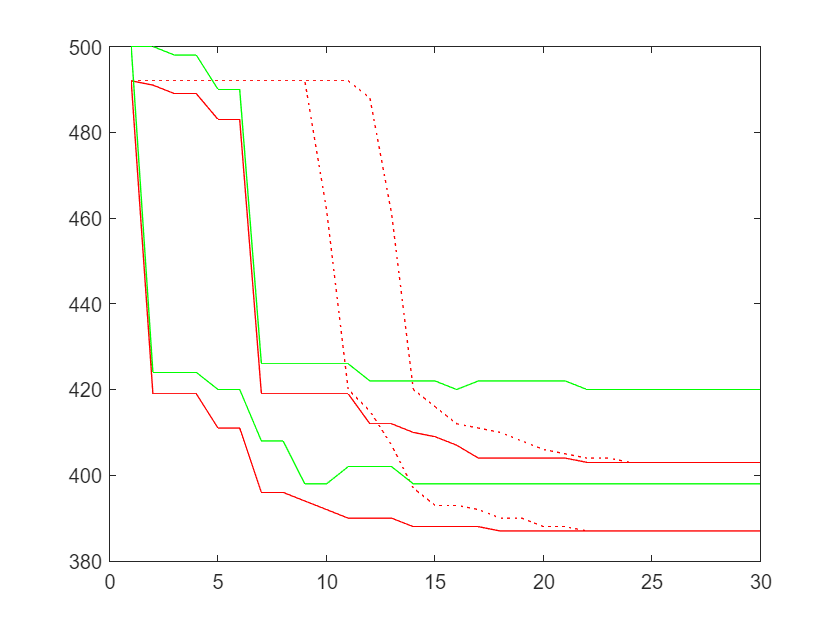


xlabel('Iteration number');
    ylabel('Objective function value');
for i=1:n

 plot(BestHistory(i,:),'Color','r'); hold on      
   plot(CurrentHistory(i,:),'Color','r','LineStyle',':'); 
   
    
end
for i=1:n
plot(FitnessOnValidation(i,:)*2,'g')
end
hold off;

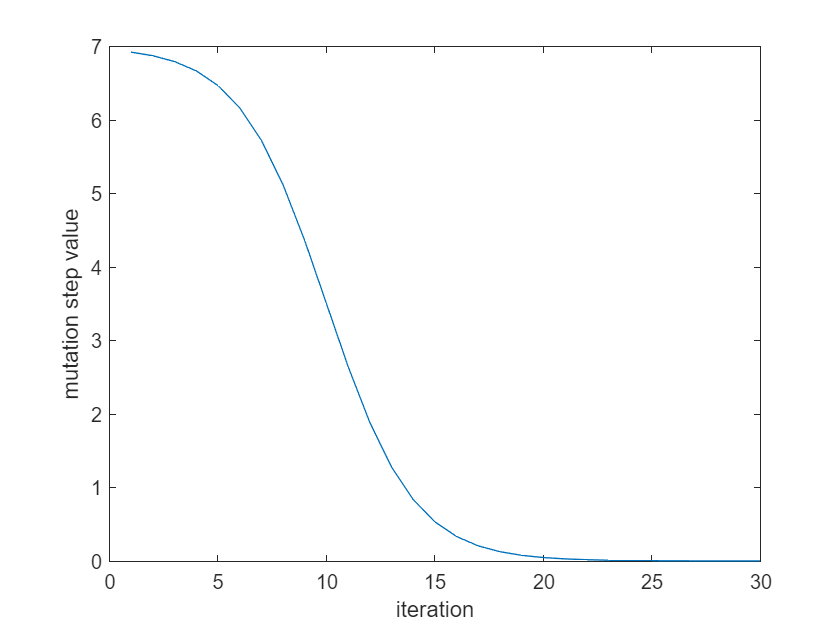

plot(Step(1,:))
xlabel('iteration');
ylabel('mutation step value');


disp('best indv cost>>');disp(bestresult);

best indv cost>>
   387



disp('results>>');disp(bestindv)

results>>
  1×2 struct array with fields:

    OF
    Parameters



c=zeros(n,1);
parfor i=1:n
    c(i,1)=fcost(bestindv(i).Parameters.W1,bestindv(i).Parameters.W2,bestindv(i).Parameters.B,TE_DATA);
end
disp(c);

   207
   196



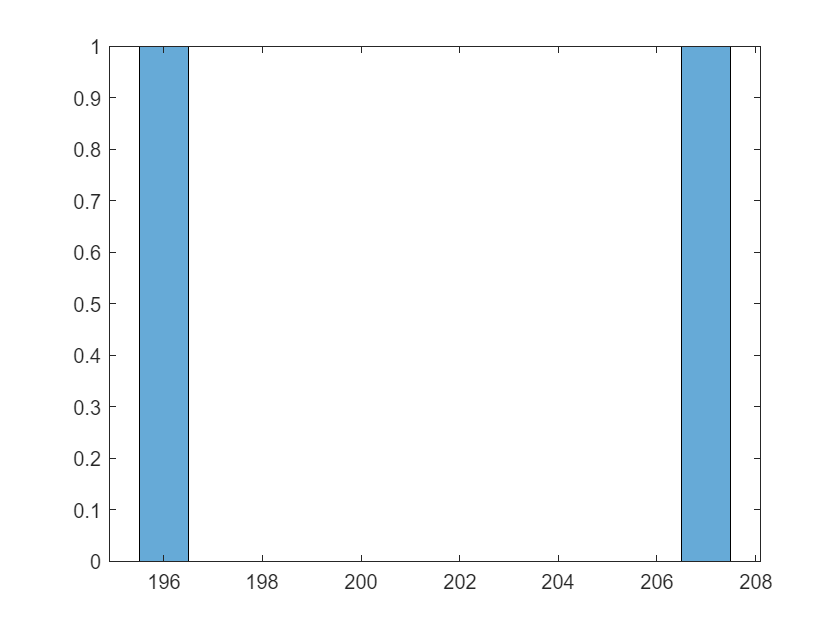

histogram(c)